load ./data/high-gamma-slow-wave-5

## Plotting single tunnel pair results histogram

chani=3

chani = 3

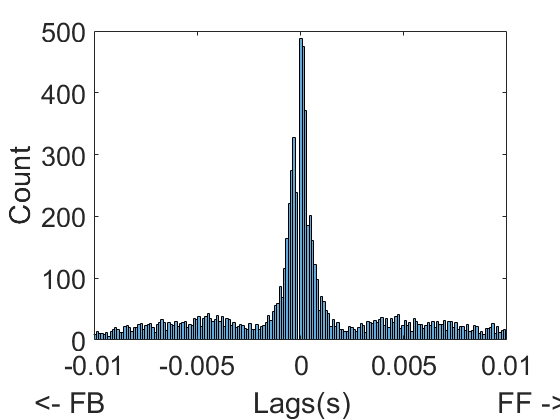

figure(1),clf
% calculating magnitude weighted (of xcov) histogram 
[histw, vinterval] = histwc(allregionresults{5}{4}{chani,2},...
    allregionresults{3}{1}{chani,1}, 320);
edges = convertCenters2edges(vinterval);
% Remove 
histw(max(find(vinterval < 0))) = 0;
histogram('BinEdges',edges,"BinCounts",histw)
xlabel("<- FB                  Lags(s)                  FF ->")
xlim([-0.01 0.01])
ylabel("Count")

## Plotting single tunnel speed histogram

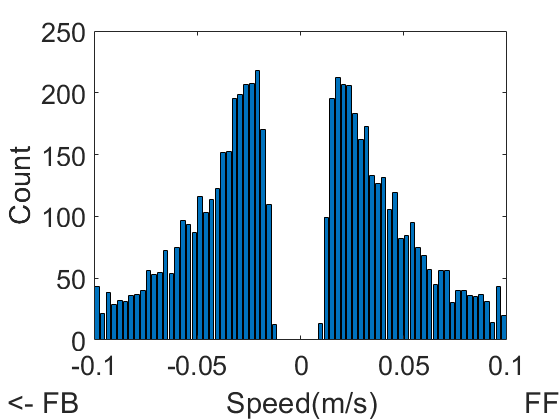


figure(2),clf
speed = 200e-6./allregionresults{3}{1}{chani,2};
corrval =  allregionresults{3}{1}{chani,1}(abs(speed) < 2);
speed = speed(abs(speed) < 2);
% calculating magnitude weighted (of xcov) histogram 
[histw, vinterval] = histwc(speed,corrval, 1201);
bar(vinterval, histw,'EdgeColor','k')
xlabel("<- FB                  Speed(m/s)                  FF ->")
xlim([-0.1 0.1])
ylabel("Count")

## Plot the time series

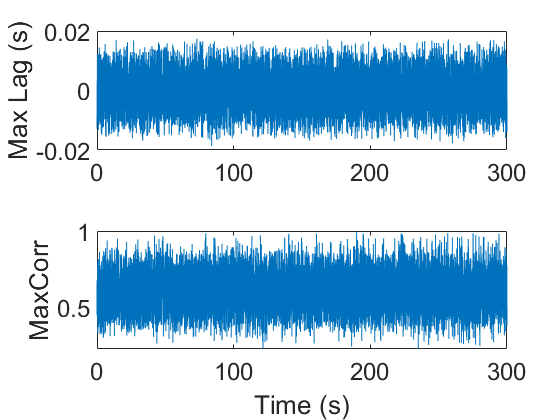

ts = allregionresults{3}{1}{6,1};
figure(3), clf
p(1)=subplot(211);
plot(ts, allregionresults{3}{1}{chani,2})
ylabel('Max Lag (s)')
p(2)=subplot(212);
plot(ts, allregionresults{3}{1}{chani,1})
ylabel('MaxCorr')
xlabel('Time (s)')

## Subregion-wise lag histogram

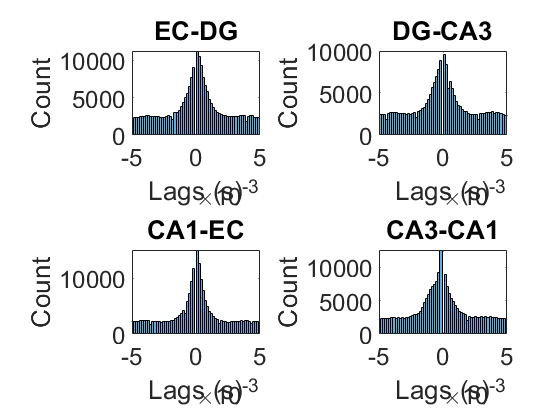

to_plot = cell(4,2);
regList = ["EC-DG", "DG-CA3", "CA3-CA1", "CA1-EC"];
for fi=3:7
    for regi = 1:4
        to_plot{regi,1} = [to_plot{regi,1} cell2mat(allregionresults{fi}{regi}(1:5,1)')];
        to_plot{regi,2} = [to_plot{regi,2} cell2mat(allregionresults{fi}{regi}(1:5,2)')];
    end
end
% 
figOrder = [1 2 4 3];
figure(4), clf
for regi = 1:4
    p(regi)=subplot(2,2, figOrder(regi));
%     [histw, vinterval] = histwc(to_plot{regi,2},to_plot{regi,1}, 320);
%     [edges] = convertCenters2edges(vinterval);
%     bar(vinterval, histw)
    h=histogram(to_plot{regi,2},241,'Visible',"off");
    binC = h.BinCounts; binE = h.BinEdges;
    binC(max(find(binE < 0))) = 0;
    histogram('BinEdges',binE, "BinCounts",binC)
    xlabel('Lags (s)')
    ylabel('Count')
    title(regList(regi))
end
linkaxes(p,'x')
    xlim([-5 5].*1e-3)

## Subregion-wise speed histogram

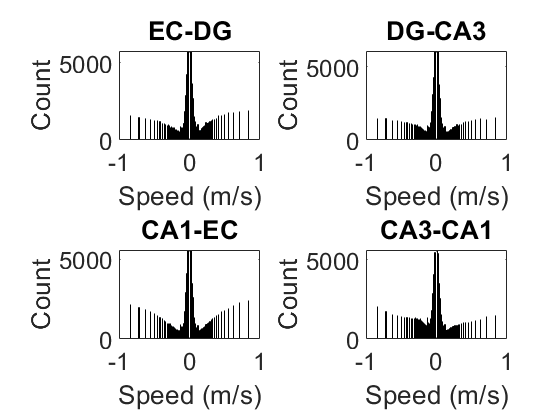


to_plot = cell(4,2);
regList = ["EC-DG", "DG-CA3", "CA3-CA1", "CA1-EC"];
figure(5), clf
for fi=3:7
    for regi = 1:4
        to_plot{regi,1} = [to_plot{regi,1} cell2mat(allregionresults{fi}{regi}(1:5,1)')];
        to_plot{regi,2} = [to_plot{regi,2} cell2mat(allregionresults{fi}{regi}(1:5,2)')];
    end
end
% 
figOrder = [1 2 4 3];
figure(4), clf
for regi = 1:4
    p(regi)=subplot(2,2, figOrder(regi));
    speed = 200e-6./to_plot{regi,2};
    corrval =  to_plot{regi,1}(abs(speed) < 1);
    speed = speed(abs(speed) < 1);
    [histw, vinterval] = histwc(speed, corrval, 501);
    bar(vinterval, histw,'EdgeColor','k')
%     histogram(to_plot{regi,2})
    xlabel('Speed (m/s)')
    ylabel('Count')
    title(regList(regi))
end
linkaxes(p,'x')
xlim([-1 1])

## Speed samples

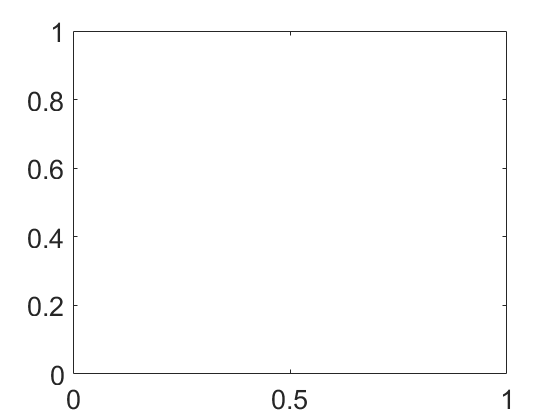

figure(6), clf
speed_samples = cell(1,4);
for fi = 3:7
    for regi = 1:4
        for chani = 1:5
            h=histogram(allregionresults{fi}{regi}{chani,2},241,'Visible',"off");
            binC = h.BinCounts; binE = h.BinEdges;
            binC(max(find(binE < 0))) = 0;
            maxlag = binE(binC == max(binC));
            maxlag = maxlag(end);
            speed_samples{regi} = [speed_samples{regi} maxlag];
        end
    end
end

## maxlag scatter

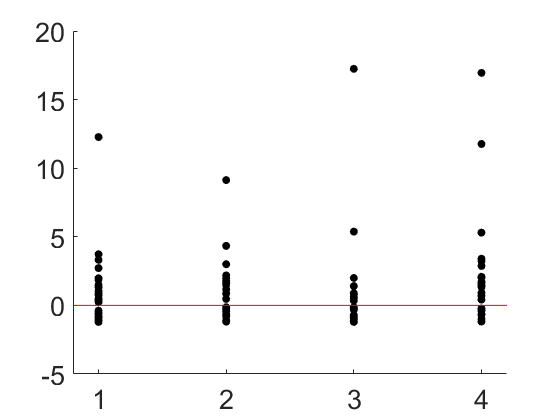

figure(7),clf
no_ele = length(speed_samples{1});
scatter([ones(1,no_ele) 2*ones(1,no_ele) 3*ones(1, no_ele) 4*ones(1, no_ele)],...
    200e-6./cell2mat(speed_samples),'filled','ok')
xlim([0.8 4.2])
hold on 
plot([0.8:0.01:4.2], zeros(1, length(0.8:0.01:4.2)), 'r')

## maxlag bar

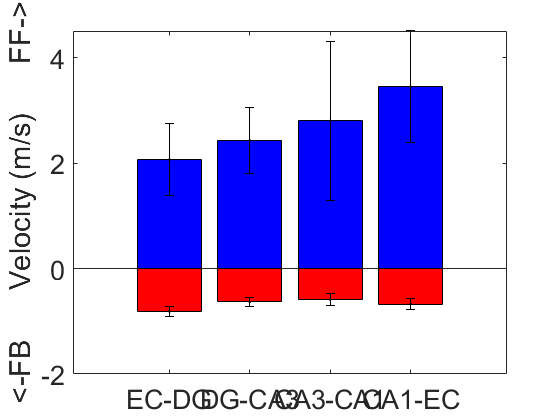

figure(8),clf
FFBar = zeros(2,4); FBBar = zeros(2,4);
for regi = 1:4
    FFBar(1,regi) = mean(200e-6./speed_samples{regi}(speed_samples{regi} > 0));
    FFBar(2,regi) = stdErr(200e-6./speed_samples{regi}(speed_samples{regi} > 0));
    FBBar(1,regi) = mean(200e-6./speed_samples{regi}(speed_samples{regi} < 0));
    FBBar(2,regi) = stdErr(200e-6./speed_samples{regi}(speed_samples{regi} < 0));
end

bar(1:4, FFBar(1,:),'b')
hold on
errorbar(1:4, FFBar(1,:), FFBar(2,:),'.k')
bar(1:4, FBBar(1,:),'r')
errorbar(1:4, FBBar(1,:), FBBar(2,:),'.k')
xticklabels(regNames)
ylabel '<-FB      Velocity (m/s)      FF->'